# Varying SNR for different methods

clc; clear; close all;

% Parameters
delta = 1/2;
theta_true = [-20, 30];
f_true = [0.1, 0.12];
d = length(theta_true);    % number of sources
M = 3;                     % number of sensors
N = 20;                    % number of snapshots
SNR_dB = 0:4:20;           % SNR range in dB
num_trials = 1000;         % Monte Carlo trials
m_smooth = 10;             % smoothing parameter for JD

% Joint diagonalization method names
methods = {'param_avg', 'diag_avg', 'selection'};
num_methods = length(methods);

% Preallocate statistics arrays for JD methods
mean_theta_joint = zeros(length(SNR_dB), d, num_methods);
std_theta_joint = zeros(length(SNR_dB), d, num_methods);
mean_phi_joint = zeros(length(SNR_dB), d, num_methods);
std_phi_joint = zeros(length(SNR_dB), d, num_methods);

% Preallocate arrays for ESPRIT
mean_theta = zeros(length(SNR_dB), d);
std_theta = zeros(length(SNR_dB), d);
mean_phi = zeros(length(SNR_dB), d);
std_phi = zeros(length(SNR_dB), d);

% Main simulation loop
for i = 1:length(SNR_dB)
    SNR = SNR_dB(i);

    % Storage for all trials
    est_theta_joint_all = zeros(num_trials, d, num_methods);
    est_phi_joint_all = zeros(num_trials, d, num_methods);
    
    est_theta_esprit_all = zeros(num_trials, d);
    est_phi_esprit_all = zeros(num_trials, d);

    for trial = 1:num_trials
        % Generate data
        [X, ~, ~] = gendata(M, N, delta, theta_true, f_true, SNR);

        % --- ESPRIT Estimation ---
        est_theta_esprit = sort(esprit(X, d));
        est_phi_esprit = sort(espritfreq(X, d));

        est_theta_esprit_all(trial, :) = est_theta_esprit;
        est_phi_esprit_all(trial, :) = est_phi_esprit;

        % --- Joint Diagonalization Methods ---
        for m = 1:num_methods
            switch methods{m}
                case 'param_avg'
                    [phi_j, theta_j] = joint_diagonalization_parameter_averaging(X, m_smooth);
                case 'diag_avg'
                    [phi_j, theta_j] = joint_diagonalization_diagonal_averaging(X, m_smooth);
                case 'selection'
                    [phi_j, theta_j] = joint_diagonalization_selection(X, m_smooth);
            end

            est_theta_joint_all(trial,:,m) = sort(theta_j);
            est_phi_joint_all(trial,:,m) = sort(phi_j);
        end
    end

    % --- Compute stats for ESPRIT ---
    mean_theta(i,:) = mean(est_theta_esprit_all);
    std_theta(i,:) = std(est_theta_esprit_all);

    mean_phi(i,:) = mean(est_phi_esprit_all);
    std_phi(i,:) = std(est_phi_esprit_all);

    % --- Compute stats for JD methods ---
    for m = 1:num_methods
        mean_theta_joint(i,:,m) = mean(est_theta_joint_all(:,:,m));
        std_theta_joint(i,:,m) = std(est_theta_joint_all(:,:,m));

        mean_phi_joint(i,:,m) = mean(est_phi_joint_all(:,:,m));
        std_phi_joint(i,:,m) = std(est_phi_joint_all(:,:,m));
    end
end


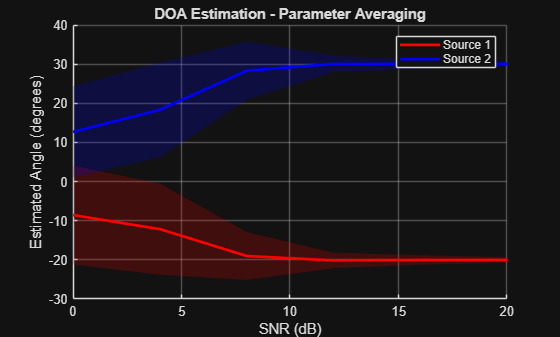

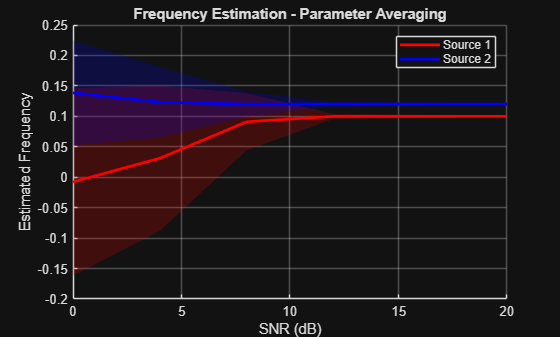

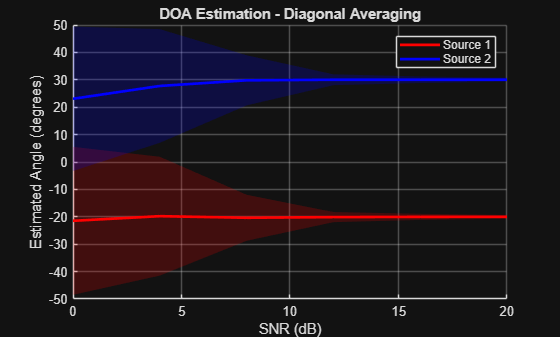

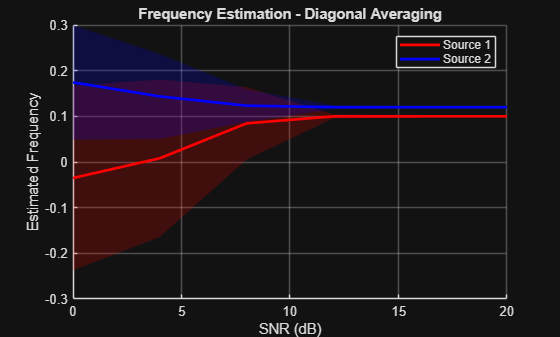

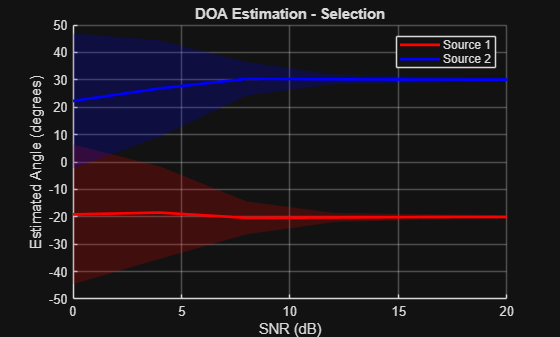

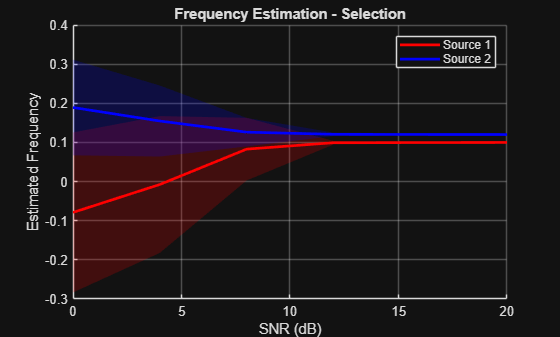

for m = 1:3
    method_names = {'Parameter Averaging', 'Diagonal Averaging', 'Selection'};
    colors = {'r', 'b'};

    %% DOA Plot
    figure;
    hold on;
    for j = 1:d
        mu = mean_theta_joint(:, j, m);
        sigma = std_theta_joint(:, j, m);
        upper = mu + sigma;
        lower = mu - sigma;

        fill([SNR_dB'; flipud(SNR_dB')], [upper; flipud(lower)], ...
             colors{j}, 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'HandleVisibility', 'off');
        plot(SNR_dB, mu, 'Color', colors{j}, 'LineWidth', 2);
    end
    xlabel('SNR (dB)');
    ylabel('Estimated Angle (degrees)');
    title(['DOA Estimation - ', method_names{m}]);
    legend('Source 1', 'Source 2');
    grid on;

    %% Frequency Plot
    figure;
    hold on;
    for j = 1:d
        mu = mean_phi_joint(:, j, m);
        sigma = std_phi_joint(:, j, m);
        upper = mu + sigma;
        lower = mu - sigma;

        fill([SNR_dB'; flipud(SNR_dB')], [upper; flipud(lower)], ...
             colors{j}, 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'HandleVisibility', 'off');
        plot(SNR_dB, mu, 'Color', colors{j}, 'LineWidth', 2);
    end
    xlabel('SNR (dB)');
    ylabel('Estimated Frequency');
    title(['Frequency Estimation - ', method_names{m}]);
    legend('Source 1', 'Source 2');
    grid on;
end

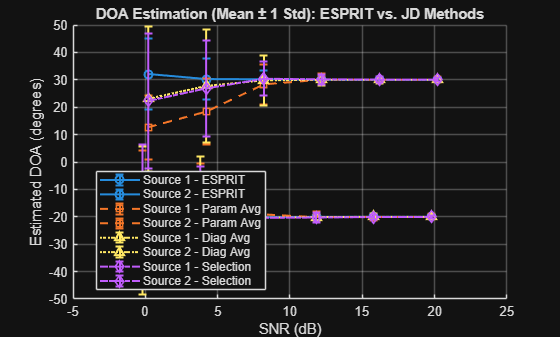


method_names = {'ESPRIT', 'Param Avg', 'Diag Avg', 'Selection'};
method_styles = {'-o', '--s', ':^', '-.d'};  % Line+marker styles
colors = lines(4);  % Distinct colors for 4 methods

%% DOA Plot
figure;
hold on;
for m = 1:4  % 1 = ESPRIT, 2–4 = JD methods
    for j = 1:d
        if m == 1
            mu = mean_theta(:, j);
            sigma = std_theta(:, j);
        else
            mu = mean_theta_joint(:, j, m - 1);  % JD method index is m - 1
            sigma = std_theta_joint(:, j, m - 1);
        end
        offset = (j - 1.5) * 0.4;  % source 1 = -0.2, source 2 = +0.2
        errorbar(SNR_dB + offset, mu, sigma, method_styles{m}, ...
            'Color', colors(m,:), 'LineWidth', 1.5, ...
            'DisplayName', sprintf('Source %d - %s', j, method_names{m}));
    end
end
xlabel('SNR (dB)');
ylabel('Estimated DOA (degrees)');
title('DOA Estimation (Mean ± 1 Std): ESPRIT vs. JD Methods');
legend('Location', 'best');
grid on;

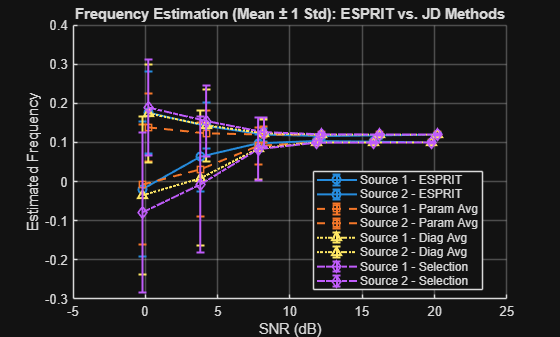


%% Frequency Plot
figure;
hold on;
for m = 1:4
    for j = 1:d
        if m == 1
            mu = mean_phi(:, j);
            sigma = std_phi(:, j);
        else
            mu = mean_phi_joint(:, j, m - 1);
            sigma = std_phi_joint(:, j, m - 1);
        end
        offset = (j - 1.5) * 0.4;
        errorbar(SNR_dB + offset, mu, sigma, method_styles{m}, ...
            'Color', colors(m,:), 'LineWidth', 1.5, ...
            'DisplayName', sprintf('Source %d - %s', j, method_names{m}));
    end
end
xlabel('SNR (dB)');
ylabel('Estimated Frequency');
title('Frequency Estimation (Mean ± 1 Std): ESPRIT vs. JD Methods');
legend('Location', 'best');
grid on;

# Varying Smoothing Factor

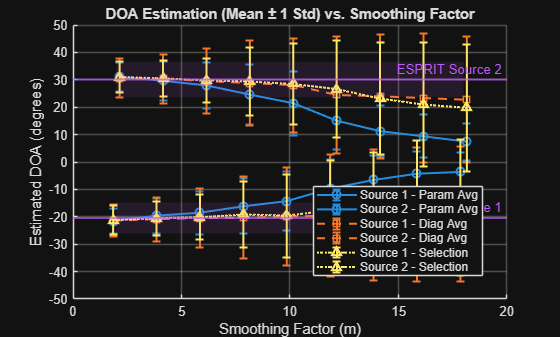

clc; clear; close all;

% Parameters
delta = 1/2;
theta_true = [-20, 30];
f_true = [0.1, 0.12];
d = length(theta_true);
M = 3;
N = 20;
SNR_fixed = 5;            % fixed SNR in dB
num_trials = 1000;
m_values = 2:2:19;        % varying smoothing factors
num_m = length(m_values);

methods = {'param_avg', 'diag_avg', 'selection'};
num_methods = length(methods);

% Allocate arrays for ESPRIT (no dependence on m)
mean_theta = zeros(1, d);
std_theta = zeros(1, d);
mean_phi = zeros(1, d);
std_phi = zeros(1, d);

% Allocate arrays for JD over m
mean_theta_joint = zeros(num_m, d, num_methods);
std_theta_joint = zeros(num_m, d, num_methods);
mean_phi_joint = zeros(num_m, d, num_methods);
std_phi_joint = zeros(num_m, d, num_methods);

% First, compute ESPRIT once as baseline
est_theta_esprit_all = zeros(num_trials, d);
est_phi_esprit_all = zeros(num_trials, d);

for trial = 1:num_trials
    [X, ~, ~] = gendata(M, N, delta, theta_true, f_true, SNR_fixed);
    est_theta_esprit_all(trial, :) = sort(esprit(X, d));
    est_phi_esprit_all(trial, :) = sort(espritfreq(X, d));
end

mean_theta(1,:) = mean(est_theta_esprit_all);
std_theta(1,:) = std(est_theta_esprit_all);
mean_phi(1,:) = mean(est_phi_esprit_all);
std_phi(1,:) = std(est_phi_esprit_all);

% Now sweep smoothing factors for JD methods
for idx = 1:num_m
    m_smooth = m_values(idx);
    
    est_theta_joint_all = zeros(num_trials, d, num_methods);
    est_phi_joint_all = zeros(num_trials, d, num_methods);

    for trial = 1:num_trials
        [X, ~, ~] = gendata(M, N, delta, theta_true, f_true, SNR_fixed);

        for m = 1:num_methods
            switch methods{m}
                case 'param_avg'
                    [phi_j, theta_j] = joint_diagonalization_parameter_averaging(X, m_smooth);
                case 'diag_avg'
                    [phi_j, theta_j] = joint_diagonalization_diagonal_averaging(X, m_smooth);
                case 'selection'
                    [phi_j, theta_j] = joint_diagonalization_selection(X, m_smooth);
            end

            est_theta_joint_all(trial,:,m) = sort(theta_j);
            est_phi_joint_all(trial,:,m) = sort(phi_j);
        end
    end

    % Compute stats for JD methods at this m
    for m = 1:num_methods
        mean_theta_joint(idx,:,m) = mean(est_theta_joint_all(:,:,m));
        std_theta_joint(idx,:,m) = std(est_theta_joint_all(:,:,m));
        mean_phi_joint(idx,:,m) = mean(est_phi_joint_all(:,:,m));
        std_phi_joint(idx,:,m) = std(est_phi_joint_all(:,:,m));
    end
end

method_names = {'Param Avg', 'Diag Avg', 'Selection'};
method_styles = {'-o', '--s', ':^'};
colors = lines(4);  % 3 for JD methods, 1 for ESPRIT

%% DOA Plot (Mean ± 1 Std vs. Smoothing Factor)
figure; hold on;
for m = 1:3
    for j = 1:d
        mu = mean_theta_joint(:, j, m);
        sigma = std_theta_joint(:, j, m);
        offset = (j - 1.5) * 0.3;
        errorbar(m_values + offset, mu, sigma, method_styles{m}, ...
            'Color', colors(m,:), 'LineWidth', 1.5, ...
            'DisplayName', sprintf('Source %d - %s', j, method_names{m}));
    end
end

% ESPRIT baseline (mean ± std as horizontal band)
for j = 1:d
    mu_esprit = mean_theta(1, j);
    std_esprit = std_theta(1, j);
    yline(mu_esprit, '-', sprintf('ESPRIT Source %d', j), ...
        'Color', colors(4,:), 'LineWidth', 1.5, 'HandleVisibility', 'off');
    % Shaded band
    fill([m_values(1) m_values(end) m_values(end) m_values(1)], ...
         [mu_esprit+std_esprit mu_esprit+std_esprit mu_esprit-std_esprit mu_esprit-std_esprit], ...
         colors(4,:), 'FaceAlpha', 0.1, 'EdgeColor', 'none', 'HandleVisibility', 'off');
end

xlabel('Smoothing Factor (m)');
ylabel('Estimated DOA (degrees)');
title('DOA Estimation (Mean ± 1 Std) vs. Smoothing Factor');
legend('Location', 'best');
grid on;

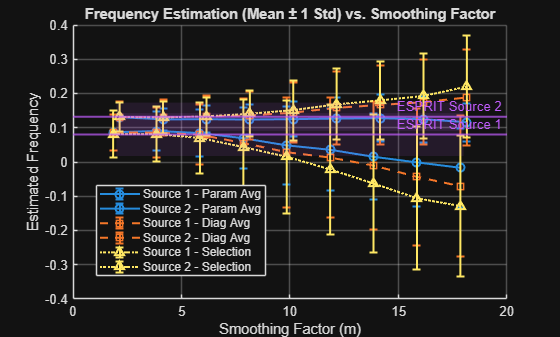


%% Frequency Plot (Mean ± 1 Std vs. Smoothing Factor)
figure; hold on;
for m = 1:3
    for j = 1:d
        mu = mean_phi_joint(:, j, m);
        sigma = std_phi_joint(:, j, m);
        offset = (j - 1.5) * 0.3;
        errorbar(m_values + offset, mu, sigma, method_styles{m}, ...
            'Color', colors(m,:), 'LineWidth', 1.5, ...
            'DisplayName', sprintf('Source %d - %s', j, method_names{m}));
    end
end

% ESPRIT baseline
for j = 1:d
    mu_esprit = mean_phi(1, j);
    std_esprit = std_phi(1, j);
    yline(mu_esprit, '-', sprintf('ESPRIT Source %d', j), ...
        'Color', colors(4,:), 'LineWidth', 1.5, 'HandleVisibility', 'off');
    fill([m_values(1) m_values(end) m_values(end) m_values(1)], ...
         [mu_esprit+std_esprit mu_esprit+std_esprit mu_esprit-std_esprit mu_esprit-std_esprit], ...
         colors(4,:), 'FaceAlpha', 0.1, 'EdgeColor', 'none', 'HandleVisibility', 'off');
end

xlabel('Smoothing Factor (m)');
ylabel('Estimated Frequency');
title('Frequency Estimation (Mean ± 1 Std) vs. Smoothing Factor');
legend('Location', 'best');
grid on;